[audio,fs] = audioread('samples/TROTRO/raw/XC818793.mp3');
audio = mono(audio);
audio = audio(0.25*fs:1.25*fs);

frameSizeMs = 3;
frameSize = floor((3/1000)*fs);
overlapSize = frameSize/2;
frames = buffer(audio,frameSize,overlapSize,'nodelay');
window = hann(frameSize);
windowedFrames = frames .* window;
energy = sum(windowedFrames.^2,1);
energyDb = 10 * log10(energy);
% normalize to 0db
energyDb = energyDb - max(energyDb);
initNoiseDb = min(energyDb);
initThreshDb = initNoiseDb/2;
numFrames = size(windowedFrames,2);
noiseDb = initNoiseDb;
threshDb = initThreshDb;
onsets = zeros(1,numFrames);
offsets = zeros(1,numFrames);
sigMarkers = zeros(1,numFrames);
sigMarker = false;
% for i = 1:2
for i = 1:numFrames
    frameEnergy = energyDb(1,i);
    if frameEnergy > threshDb
        sigMarkers(i) = 1;
        if ~sigMarker
            onsets(i) = 1;
            sigMarker = true;
        end
    else
        if sigMarker
            offsets(i) = 1;
            sigMarker = false;
        else
            if i > 1
                processedNonSyllableFrames = find(~sigMarkers(:,1:i-1));
                noiseDb = mean(energyDb(processedNonSyllableFrames));
                threshDb = noiseDb/2;
            end
        end
    end
end

% syllable merging
mergeThreshMs = 15;
mergeThreshFrames = (mergeThreshMs*2)/frameSizeMs;
mergedSm = sigMarkers;
mergedOff = offsets;
mergedOns = onsets;
onsetIndices = find(onsets);
offsetIndices = find(offsets);
% if same number of offsets as onsets then we can ignore last offset
if numel(onsetIndices) == numel(offsetIndices)
    offsetIndices = offsetIndices(1:end-1);
end
syllableDists = onsetIndices(2:end)-offsetIndices;
mergeCandidateIndices = find(syllableDists <= mergeThreshFrames);
for ii = mergeCandidateIndices
    oi = offsetIndices(ii);
    ol = oi+syllableDists(ii);
    mm = oi:ol;
    mergedSm(mm) = 1;
    mergedOff(oi) = 0;
    mergedOns(ol) = 0;
end

markedSamples = zeros(size(audio));
for ii = find(mergedSm)
    ss = (ii - 1) * overlapSize + 1;
    se = ss + frameSize - 1;
    markedSamples(ss:se) = 1;
end
syllableBoundaries = find(diff(markedSamples) ~= 0) + 1;

plot(audio)
xlim([0 numel(audio)])
xlabel('Sample index')
ylabel('Amplitude')

plot(energyDb)
xlim([0 numel(energyDb)])
xlabel('Frame index')
ylabel('Energy (db)')

hold on
plot(find(onsets),-5,'g^','MarkerSize', 10)
plot(find(offsets),-5,'rv','MarkerSize', 10)
hold off

syllMidPoints = (syllableBoundaries(1:2:end)+syllableBoundaries(2:2:end))/2;
syllLabels = {'A', 'B', 'C', 'D', 'E', 'F', 'G'};

T = (0:numel(audio)-1)/fs;

t = tiledlayout(2,2);
t.TileSpacing = "compact";

ax1 = nexttile;
plot(ax1,T,audio)
% xlim([0 numel(T)])
xlabel('Time (s)')
ylabel('Amplitude')

ax2 = nexttile;
plot(ax2,energyDb)
hold(ax2,'on')
plot(find(onsets),-5,'g^','MarkerSize', 10)
plot(find(offsets),-5,'rv','MarkerSize', 10)
yline(threshDb,'m--')
% yline(noiseDb,'m-')
hold(ax2,'off')
xlim([0 numel(energyDb)])
xlabel('Frame index')
ylabel('Energy (dB)')

ax3 = nexttile;
plot(ax3,energyDb)
hold(ax3,'on')
plot(find(mergedOns),-5,'g^','MarkerSize', 10)
plot(find(mergedOff),-5,'rv','MarkerSize', 10)
hold(ax3,'off')
xlim([0 numel(energyDb)])
xlabel('Frame index')
ylabel('Energy (dB)')

ax4 = nexttile;
plot(ax4,T,audio)
hold(ax4,'on')
xline(syllableBoundaries/fs,'LineWidth',1)
text(syllMidPoints/fs,ones(1,7)*0.13,syllLabels,'HorizontalAlignment','center')
hold(ax4,'off')
% xlim([0 numel(T)])
xlabel('Time (s)')
ylabel('Amplitude')

[audio,fs] = audioread('samples/TROTRO/raw/XC818793.mp3');
audio = mono(audio);
audio = audio(0.3*fs:1.54*fs);
[syllables,~,boundaries] = segmentSyllables(audio,fs);
toDel = [];
for i = 1:2:numel(boundaries)
    if boundaries(i+1)-boundaries(i) < 264
        toDel = [toDel i i+1];
    end
end
T = (0:numel(audio)-1)/fs;
boundaries(toDel) = [];
b = boundaries;
s = syllables;
plot(T,audio)
hold on
xline(b/fs)
hold off
xlim([0 T(end)])

c1 = [0 0.4470 0.7410];
c2 = [0.8500 0.3250 0.0980];
c3 = [0.9290 0.6940 0.1250];
c4 = [0.4940 0.1840 0.5560];
c5 = [0.4660 0.6740 0.1880];
c6 = [0.3010 0.7450 0.9330];
c7 = [0.6350 0.0780 0.1840];
c8 = [1 0.6 1];
c9 = [0 0 102]/255;
c10 = [204 204 0]/255;
C = [c2;c3;c4;c5;c6;c7;c8;c9;c10];

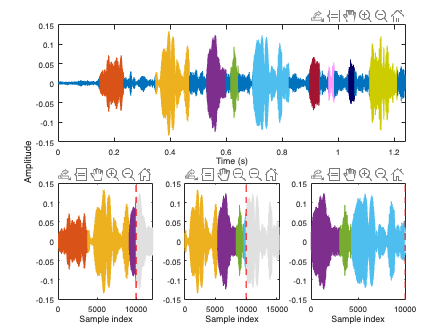

t = tiledlayout(2,3);
t.TileSpacing = "compact";

nexttile(1,[1 3]);
plot(T(1:b(1)),audio(1:b(1)),'Color',c1)
xlim([0 T(end)])
xlabel('Time (s)')
hold on
plot(T(b(end):end),audio(b(end):end),'Color',c1)
for i = 1:2:numel(b)-1
    plot(T(b(i):b(i+1)),s{(i+1)/2},'Color',C((i+1)/2,:))
    if i+2>numel(b)
        ei = numel(b);
    else
        ei = i+2;
    end
    plot(T(b(i+1):b(ei)),audio(b(i+1):b(ei)),'Color',c1)
end
plot(T(b(end):end),audio(b(end):end),'Color',c1)
hold off

nexttile;
plot(s{1},'Color',C(1,:))
hold on
t1 = numel(s{1});
t2 = t1+numel(s{2})-1;
r1 = t1:t2;
plot(t1:t2,s{2},'Color',C(2,:))
t3 = t2+numel(s{3})-1;
r2 = t2:min(t3,1e4);
plot(t2:min(t3,1e4),s{3}(1:numel(r2)),'Color',C(3,:))
plot(1e4:1e4+numel(s{3})-numel(r2),s{3}(numel(r2):end),'Color',[224 224 224]/255)
xline(1e4,'r--','LineWidth',2)
hold off
xlim([0 1e4+numel(s{3})-numel(r2)])
title('Sequence 1')
xlabel('Sample index')

nexttile
plot(s{2},'Color',C(2,:))
hold on
t1 = numel(s{2});
t2 = t1+numel(s{3})-1;
r1 = t1:t2;
plot(r1,s{3},'Color',C(3,:))
t3 = t2+numel(s{4})-1;
r2 = t2:t3;
plot(r2,s{4},'Color',C(4,:))
t4 = t3+numel(s{5})-1;
r3 = t3:1e4;
plot(r3,s{5}(1:numel(r3)),'Color',C(5,:))
xline(1e4,'r--','LineWidth',2)
plot(1e4:1e4+numel(s{5})-numel(r3),s{5}(numel(r3):end),'Color',[224 224 224]/255)
hold off
% xlim([0 1e4+numel(s{4})-numel(r2)])
title('Sequence 2')
xlabel('Sample index')

nexttile
plot(s{3},'Color',C(3,:))
hold on
t1 = numel(s{3});
t2 = t1+numel(s{4})-1;
r1 = t1:t2;
plot(t1:t2,s{4},'Color',C(4,:))
t3 = t2+numel(s{5})-1;
r2 = t2:min(t3,1e4);
plot(t2:min(t3,1e4),s{5}(1:numel(r2)),'Color',C(5,:))
plot(1e4:1e4+numel(s{5})-numel(r2),s{5}(numel(r2):end),'Color',[224 224 224]/255)
xline(1e4,'r--','LineWidth',2)
hold off
xlim([0 1e4+numel(s{5})-numel(r2)])
title('Sequence 3')
xlabel('Sample index')

ylabel(t,'Amplitude')

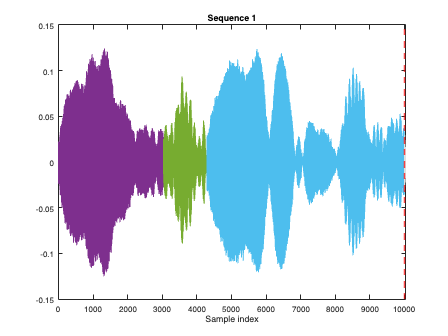

figure;
plot(s{3},'Color',C(3,:))
hold on
t1 = numel(s{3});
t2 = t1+numel(s{4})-1;
r1 = t1:t2;
plot(t1:t2,s{4},'Color',C(4,:))
t3 = t2+numel(s{5})-1;
r2 = t2:min(t3,1e4);
plot(t2:min(t3,1e4),s{5}(1:numel(r2)),'Color',C(5,:))
plot(1e4:1e4+numel(s{5})-numel(r2),s{5}(numel(r2):end),'Color',[224 224 224]/255)
xline(1e4,'r--','LineWidth',2)
hold off
xlim([0 1e4+numel(s{5})-numel(r2)])
title('Sequence 1')
xlabel('Sample index')